cwd = fileparts(matlab.desktop.editor.getActiveFilename);%import functions from src
src_path = fullfile(cwd, "src")

src_path = "/home/ben/ibots/iBOTS-Tools/workshops/matlab-workshop-1/plan/day1/src"

userpath(src_path)

# Introduction to Matlab Live Scripts

Have you ever seen a wall of code like so that doesn't make any sense to you? 

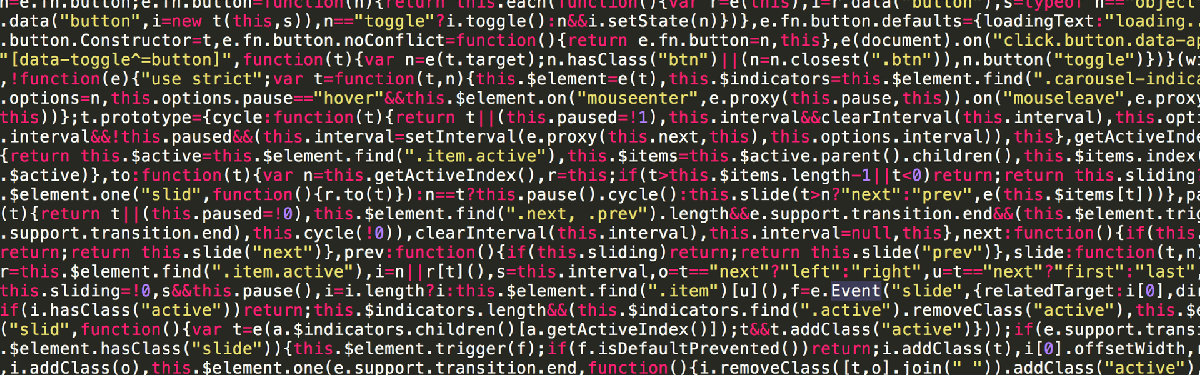

A Matlab live script is the perfect antitode! 

With a live script, we can write and run Matlab code with added bonuses: 

- Annotate code with formatted text (eg. bullet points, section headers, hyperlinks and more

- split code up into sections that can be run independantly 

- Illustrate code with images

In this session we will go through the basic features of a live script and how to work with Matlab.

## Your First Live Script 

### Writing Code and Text

To make a new Live Script, select Live Script from the New menu in the upper left corner.

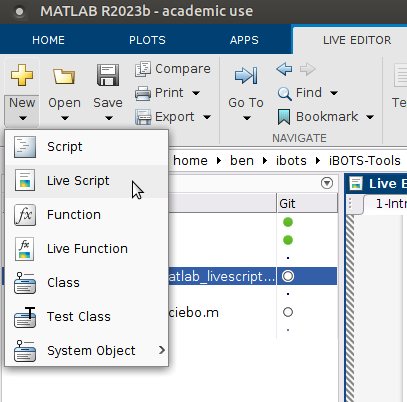

In the new live script, you can immediately start writing Matlab code.

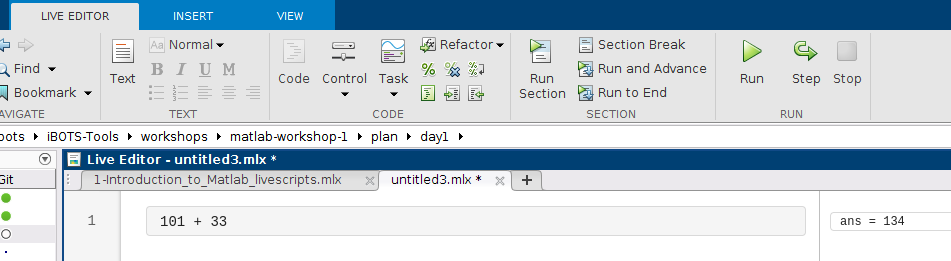

Run the whole live script by pressing the green "Run" arrow on the top right and the code's output is displayed on the right.

To switch between writing code and text, use the "Text" and "Code" buttons on the top menu

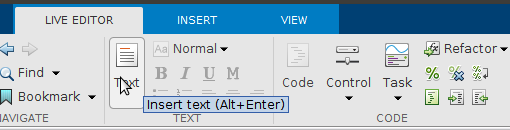

### Sections

A live script can be split into sections that run independantly. To make a new section, press the "Section Break" button on the top menu.

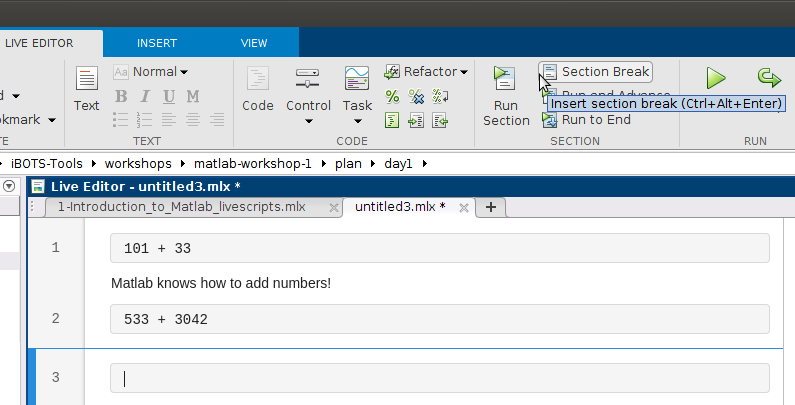

Sections are divided by pale blue lines and the section you are currently working on is highlighted by a blue box.

To execute the code in a section, press the "Run Section" button (or use Ctrl + Enter). Note that this is different from the "Run" button, which runs all sections of the live script.

Feel free to experiment with sections, writing and formatting text and writing code!

## Coding in Matlab

Matlab was first developed in the late 1970s, making it one of the oldest programming languages that is still widely used today. It was initially for carrying out matrix calculations, and these roots are still visible today. 

For example, let's define an array of numbers

my_array = [0,2,4,7,9]

my_array =      0     2     4     7     9


This is shown in the output on the right as a "1x5" matrix. What happens when we do a transpose? This is done with an apostrophe '

my_array' % perform a transpose on my_array

ans =      0
     2
     4
     7
     9


Now it is a "5x1" matrix. 

Matlab is a communicative programming language- the output of every line of code is displayed in the panel on the right. To silence this output, simply end the line with a semi-colon ;

my_second_array = [1,1,1,2,2]; % shut matlab up with a semi-colon

and no output is given. This is a handy feature because it eliminates the need for print statements.

As seen from the code above, comments in Matlab are made with the % sign.

To show off Matlab's matrix capabilities, we can multiply our two arrays

We cannot just do 

because it breaks the rules of matrix multiplication! Instead we must transpost one of the arrays

my_second_array'* my_array

ans =      0     2     4     7     9
     0     2     4     7     9
     0     2     4     7     9
     0     4     8    14    18
     0     4     8    14    18


or

my_second_array* my_array'

ans = 38

Notice how we get very different answers depending on which is transposed - that's matrix multiplication.

In data analysis however, when you want to multiply two arrays, you probably want to multiply them element-wise. We can do this like so

my_second_array.* my_array % note the .

ans =      0     2     4    14    18


It is important to keep in mind that Matlab understands and expects everything to be in terms of matrices. 

### Workspace variables

Matlab makes it easy to keep track of our variables with the Workspace. Variable names and values are listed in the rightmost pane.

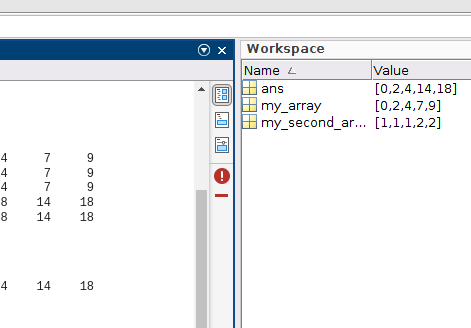

We can see that values of` my_array `and `my_second_array. `

We also see` ans `(short for answer)` - `this is the value of the last output. 

Let's run the section below and see what happens to `ans `

"the answer has changed!"

ans = "the answer has changed!"

When a variable in the Workspace is double clicked, it is displayed in its entirety in a Excel-like spreadsheet. 

Let's load in some data about different cereals and look at the Workspace

load cereal.mat

All variables are deleted from the workspace by right clicking on the pane and choosing "clear workspace"

### Matlab Tables

A handy way of storing large amounts of data is in a table. Let's explore some features of a table

- download data from sciebo

- show structure of table

- basic functions, head, tail, indexing, so on 

We will download the raw data 

url= "https://uni-bonn.sciebo.de/s/9FxelLhARmHpw85/";
download_from_sciebo(url, 'data/steinmetz_winter2017.csv')

and load it into Matlab as a table

data = readtable("test.dat")

data = 7906×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type       mouse       session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    ___________    ____________    __________

Now `data `appears as a 7906x15 table in the Workspace. By clicking on it, we can view the tabular data and even sort by certain columns by clicking on the column names. 

## Experimental Data

In this workshop we will be analysing data of Nicholas Steinmetz and colleagues from their 2019 Nature publication. The code below will download the paper.

download_from_sciebo("https://uni-bonn.sciebo.de/s/xUrHMXlJQegOtAN", 'steinmetz2019.pdf')

In the experiment, trained mice performed a discrimination task with their choices reported by turning a steering wheel. 

The mice were presented with two stimuli a screen, one on the left and one on the right. Their task was to turn a steering wheel such that the brighter stimulus moves into the center. If the mice perform the task correctly, they are rewarded with a drink of water. 

During the experiment, neural activity was recorded via NeuroPixels probes, which are dense arrays of electrodes that can measure the activity of several hundred neurons at once. 

The dataset is a rich source with behavioural and neural data that is just waiting to be explored with Matlab!

 An excellent description of the experiment is given in this [10 minute video](https://www.youtube.com/watch?v=WXn4-FpVaOo) by the study's lead author, Nicholas Steinmetz.